Finding a solution is easy at some values of $\epsilon$. 

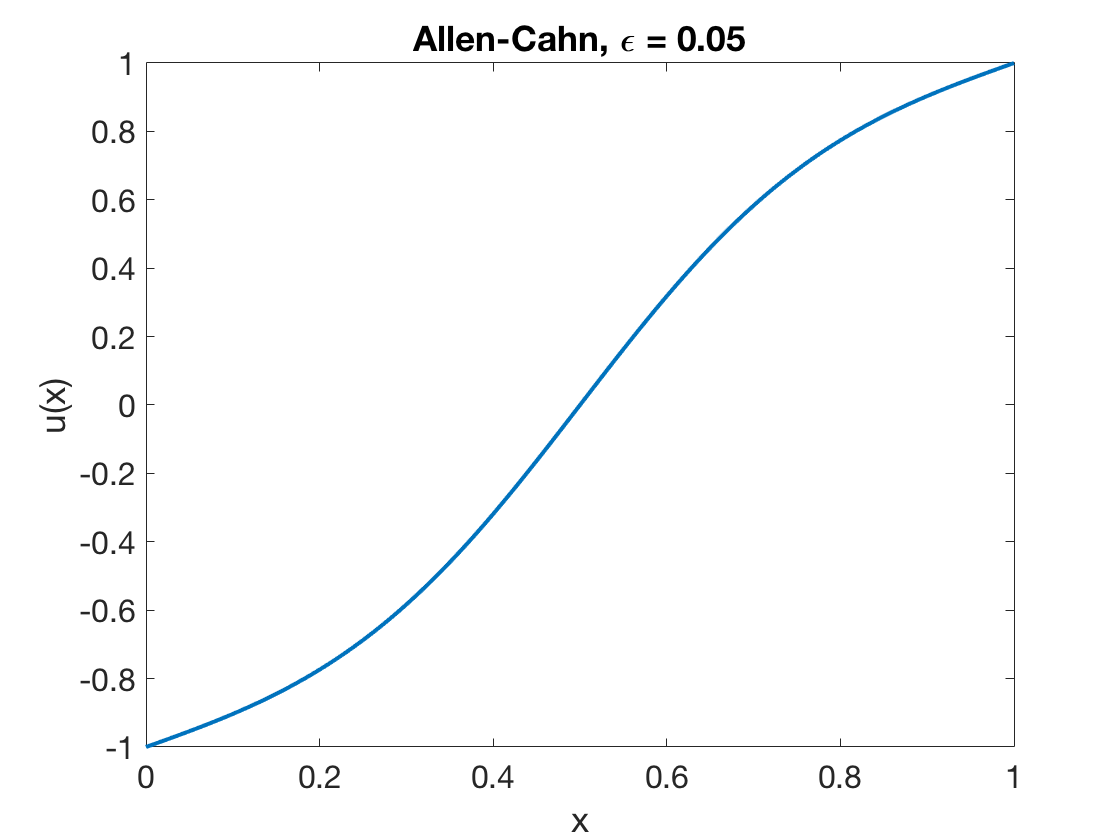

epsilon = 0.05;
phi = @(x,u,dudx) (u.^3 - u) / epsilon;
init = linspace(-1,1,141)';
[x,u1] = bvp(phi,[0,1],-1,[],1,[],init);
plot(x,u1)
xlabel('x'), ylabel('u(x)')   % ignore this line
title('Allen-Cahn, \epsilon = 0.05')   % ignore this line

However, finding a good starting guess is not trivial for smaller values of $\epsilon$. Note below that the iteration stops without converging to a solution.

epsilon = 0.005;
phi = @(x,u,dudx) (u.^3 - u) / epsilon;
warning on    % ignore this line
[x,u] = bvp(phi,[0,1],-1,[],1,[],init);

A simple way around this problem is to use the result of a solved version as the starting guess for a more difficult version.

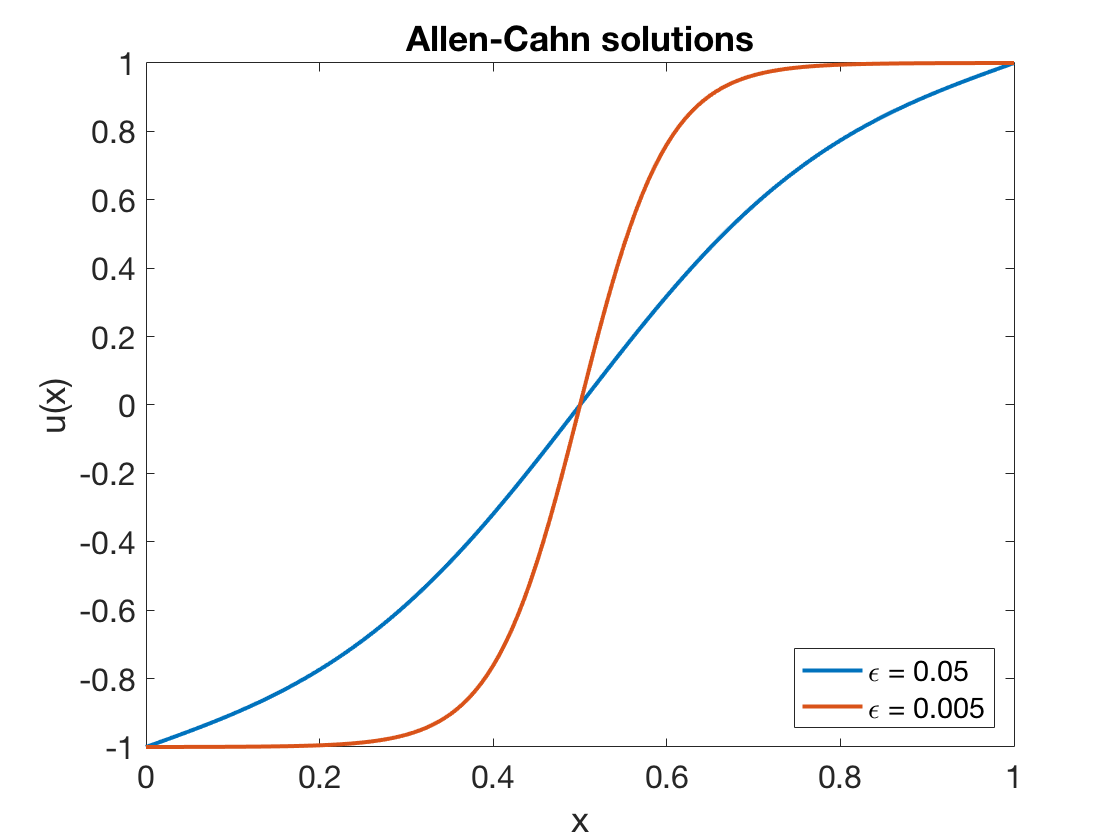

phi = @(x,u,dudx) (u.^3 - u) / 0.005;
[x,u2] = bvp(phi,[0,1],-1,[],1,[],u1);
hold on, plot(x,u2)
xlabel('x'), ylabel('u(x)')   % ignore this line
title('Allen-Cahn solutions')   % ignore this line
legend('\epsilon = 0.05','\epsilon = 0.005','location','southeast')   % ignore this line

In this case we can continue further.

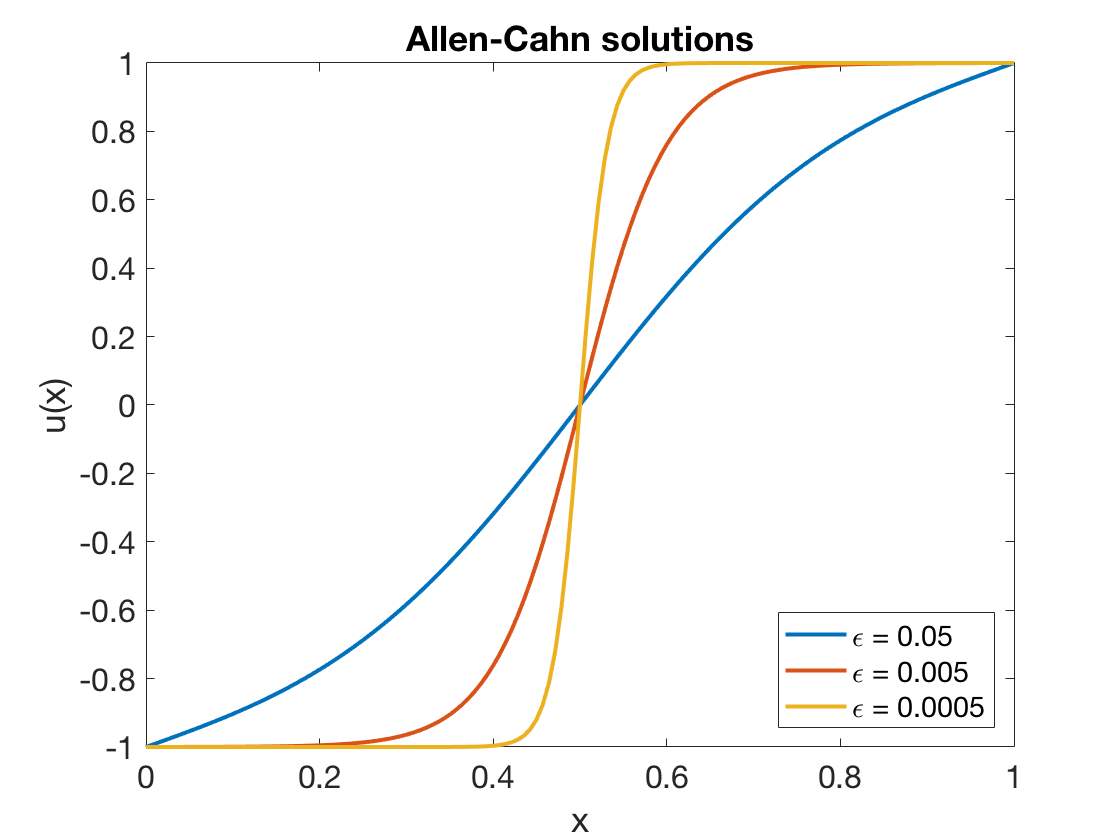

phi = @(x,u,dudx) (u.^3 - u) / 0.0005;
[x,u3] = bvp(phi,[0,1],-1,[],1,[],u2);
plot(x,u3)
xlabel('x'), ylabel('u(x)')   % ignore this line
legend('\epsilon = 0.05','\epsilon = 0.005','\epsilon = 0.0005','location','southeast')   % ignore this line